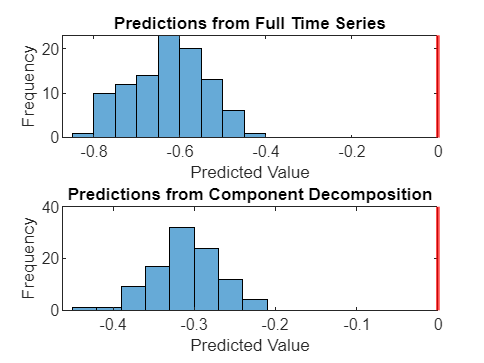

clear all;
% Parameters
N = 100;  % Number of points in the time series
num_experiments = 100;  % Number of experiments to perform

% Generate sinusoidal signals with optional exponential decay
t = (1:N)';
signal1 = sin(2 * pi * 0.1 * t) .* exp(-0.01 * t);
signal2 = sin(2 * pi * 0.05 * t) .* exp(-0.01 * t);
signal3 = sin(2 * pi * 0.02 * t) .* exp(-0.01 * t);

% Combine signals to form the time series
time_series = signal1 + signal2 + signal3;

% Ground truth for point 100
ground_truth = time_series(N);

% Prepare storage for predictions
predictions_full = zeros(num_experiments, 1);
predictions_components = zeros(num_experiments, 1);

% Add noise to the time series and perform the experiment
for exp = 1:num_experiments
    % Add noise
    noisy_series = time_series + randn(N, 1) * 0.1;  % Adjust noise level as needed

    % Full time series prediction using AR model
    model_full = ar(noisy_series(1:N-1), 1);  % AR(1) model
    pred_full = predict(model_full, noisy_series(1:N-1), 1);
    predictions_full(exp) = pred_full(end);

    % Decompose the time series into components using SSD
    [U, S, V] = svd(hankel(noisy_series(1:N-1)));
    num_components = 3;
    components = U(:, 1:num_components) * S(1:num_components, 1:num_components) * V(:, 1:num_components)';

    % Predict each component separately
    pred_components = zeros(num_components, 1);
    for comp = 1:num_components
        model_comp = ar(components(:, comp), 1);  % AR(1) model for each component
        pred_comp = predict(model_comp, components(:, comp), 1);
        pred_components(comp) = pred_comp(end);
    end
    predictions_components(exp) = sum(pred_components);
end

% Compare predictions
figure;
subplot(2, 1, 1);
histogram(predictions_full);
title('Predictions from Full Time Series');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line

subplot(2, 1, 2);
histogram(predictions_components);
title('Predictions from Component Decomposition');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line


% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp(['Mean: ', num2str(mean(predictions_full)), ', Std: ', num2str(std(predictions_full))]);

Mean: -0.62612, Std: 0.086354



disp('Component Decomposition Predictions:');

Component Decomposition Predictions:


disp(['Mean: ', num2str(mean(predictions_components)), ', Std: ', num2str(std(predictions_components))]);

Mean: -0.30792, Std: 0.039223


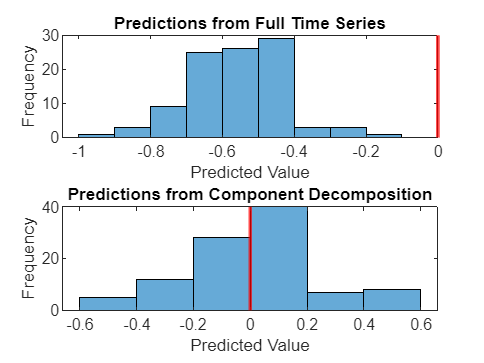

clear all;
addpath('./tensorlab');  % Ensure Tensorlab is in your path
addpath('./cvx');  % Ensure CVX is in your path

% Parameters
N = 100;  % Number of points in the time series
L = 20;   % Number of rows in each Hankel matrix
num_series = 3;  % Number of sinusoidal signals
num_experiments = 100;  % Number of experiments to perform
rank = 3;  % Rank for the CP decomposition

% Generate sinusoidal signals with optional exponential decay
t = (1:N)';
signal1 = sin(2 * pi * 0.1 * t) .* exp(-0.01 * t);
signal2 = sin(2 * pi * 0.05 * t) .* exp(-0.01 * t);
signal3 = sin(2 * pi * 0.02 * t) .* exp(-0.01 * t);

% Combine signals to form the time series matrix
time_series_matrix = [signal1, signal2, signal3];

% Ground truth for point 100
ground_truth = sum(time_series_matrix(N, :));

% Prepare storage for predictions
predictions_full = zeros(num_experiments, 1);
predictions_components = zeros(num_experiments, 1);

% Define options for CPD
options = struct;
options.Display = 0;  % Turn off display

% Add noise to the time series and perform the experiment
for exp = 1:num_experiments
    % Add noise
    noisy_tensor = time_series_matrix + randn(size(time_series_matrix)) * 0.1;  % Adjust noise level as needed

    % Full time series prediction using AR model for each series
    pred_full_sum = 0;
    for i = 1:num_series
        data = iddata(noisy_tensor(1:N-1, i), [], 1);
        ar_model = ar(data, 1);
        pred_full = predict(ar_model, data, 1);
        pred_full_sum = pred_full_sum + pred_full.OutputData(end);
    end
    predictions_full(exp) = pred_full_sum;

    % Construct 3D Hankel tensor
    H3D = zeros(L, N-L+1, num_series);
    for i = 1:num_series
        H2D = hankel(noisy_tensor(1:L, i), noisy_tensor(L:N, i));
        H3D(:, :, i) = H2D;
    end

    % Perform CP decomposition using Tensorlab
    cp_decomp = cpd(H3D, rank, options);

    % Predict each component separately
    pred_components_sum = 0;
    for comp = 1:rank
        component_data = iddata(cp_decomp{1}(:, comp), [], 1);
        ar_model_comp = ar(component_data, 1);
        pred_comp = predict(ar_model_comp, component_data, 1);
        pred_components_sum = pred_components_sum + pred_comp.OutputData(end);
    end
    predictions_components(exp) = pred_components_sum;
end

% Compare predictions
figure;
subplot(2, 1, 1);
histogram(predictions_full);
title('Predictions from Full Time Series');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line

subplot(2, 1, 2);
histogram(predictions_components);
title('Predictions from Component Decomposition');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line


% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp(['Mean: ', num2str(mean(predictions_full)), ', Std: ', num2str(std(predictions_full))]);

Mean: -0.55803, Std: 0.13654



disp('Component Decomposition Predictions:');

Component Decomposition Predictions:


disp(['Mean: ', num2str(mean(predictions_components)), ', Std: ', num2str(std(predictions_components))]);

Mean: 0.012613, Std: 0.23736
